# Load Matlab datafile

clear all;
%load(fullfile('ECG.mat'));
%load(fullfile('ECGNEW2.mat'));
%load(fullfile('ECGNEW.mat'));
%load(fullfile('PPG.mat'));
%load(fullfile('GSR.mat'));
load(fullfile('ECGPPGNB.mat'));
%load(fullfile('ECGPPGNBS.mat'));
%load(fullfile('ECGGSR.mat'));
%Data = importdata('TT2.csv');
%Data = importdata('ECGACC.csv');
TrainTestData = ECGPPGNEW.Data;
train_n_test_label = ECGPPGNEW.Labels;
%TrainTestData = ECGData.Data;
%train_n_test_label = ECGData.Labels;
%TrainTestData=[TrainD(2:end),TestD(2:end)]
%train_n_test_label=[TrainD(1:), TestD(1:)]



## Split data into testing and training set

%trainData1 = TrainTestData(:,1:45000);
%testData1 = TrainTestData(:,45001:65536);
%trainData1 = TrainTestData(:,1:8000);
%testData1 = TrainTestData(:,8001:16000);
%%trainData1 = TrainTestData(:,1:4000);
%testData1 = TrainTestData(:,4001:8000);

DataSegment1 = TrainTestData(:,1:8000);
DataSegment2 = TrainTestData(:,8001:16000);
DataSegment3 = TrainTestData(:,16001:24000);
DataSegment4 = TrainTestData(:,24001:32000);
DataSegment5 = TrainTestData(:,32001:40000);
DataSegment6 = TrainTestData(:,40001:48000);
DataSegment7 = TrainTestData(:,48001:56000);
%FinalDataSegment=DataSegment1+DataSegment2+DataSegment3+DataSegment4+DataSegment5+DataSegment6++DataSegment7;  
FinalDataSegment=vertcat(DataSegment1(1:53,:),DataSegment2(1:53,:),DataSegment3(1:53,:),DataSegment4(1:53,:),DataSegment5(1:53,:),DataSegment6(1:53,:),DataSegment7(1:53,:));
%newDataSegment1=TrainTestData2(:,1:8000);
%newDataSegment2=TrainTestData2(:,8001:16000);
%newDataSegment3=TrainTestData2(:,16001:24000);
train_n_test_label=vertcat(train_n_test_label(:),train_n_test_label(:),train_n_test_label(:),train_n_test_label(:),train_n_test_label(:),train_n_test_label(:),train_n_test_label(:));
%trainData1 = FinalDataSegment(:,1:4000);
%testData1 = FinalDataSegment(:,4001:8000);
trainData1 = FinalDataSegment(:,1:4000);
testData1 = FinalDataSegment(:,4001:8000);
%Mdl = fitcensemble(trainData1,train_n_test_label);
%predKNN = predict(Mdl,testData1);

%correctPredictionK = strcmp(predKNN,train_n_test_label);
%[confusionMatrixK] = confusionmat(train_n_test_label,predKNN);
%plotconfusion(categorical(train_n_test_label),categorical(predKNN));

## Feature extraction

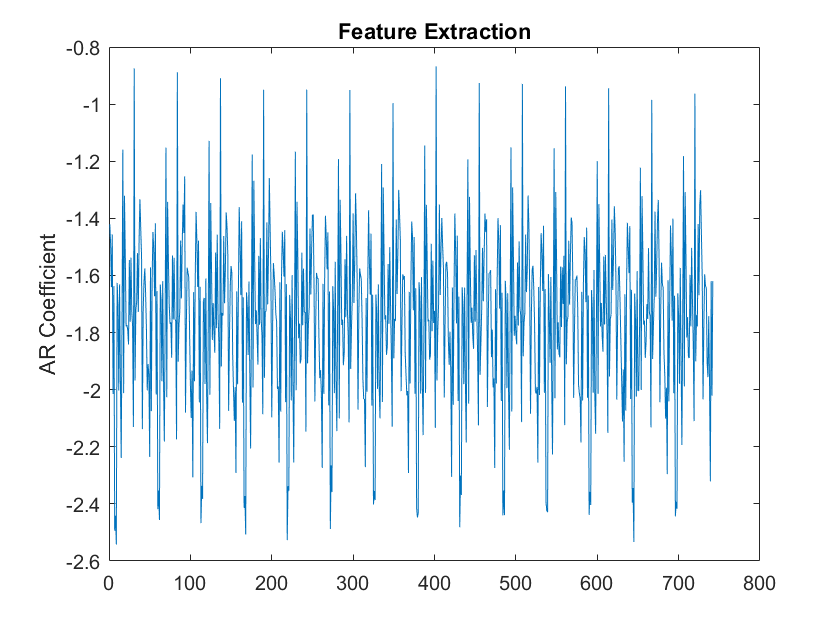

%timeWindow = 8192;
%timeWindow = 4000; % for ECGPPG, GSR
%timeWindow = 1600; % for ECGPPG, GSR
%timeWindow = 8192; % for ECGPPG, GSR
timeWindow = 4000; %For other signals
%timeWindow = 800;
%timeWindow = 600;
%AROrder = 2; %worked well before
AROrder = 8;

%transformLevel = 4;
transformLevel = 2;
%transformLevel = 5;

[trainFeatures,featureindices]=featureExtraction(trainData1,timeWindow,AROrder,transformLevel);
[testFeatures,featureindices]=featureExtraction(testData1,timeWindow,AROrder,transformLevel);
%[trainFeatures,featureindices]=featureExtraction(trainData1,timeWindow,AROrder,transformLevel);
%[testFeatures,featureindices]=featureExtraction(testData1,timeWindow,AROrder,transformLevel);
%[trainFeatures,testFeatures,featureindices] = featureExtraction(trainData1,testData1,timeWindow,AROrder,transformLevel);
%[trainFeatures,testFeatures,featureindices] = featureExtraction(trainData1,testData1,timeWindow,AROrder,transformLevel);
%[trainFeatures,testFeatures,featureindices] = featureExtraction(trainData1,testData1,timeWindow,AROrder);
%[trainFeatures,testFeatures,featureindices] = ...
    %helperExtractFeatures(trainData1,testData1,timeWindow,AROrder,transformLevel);

%[trainFeatures,testFeatures,featureindices] = featureExtraction(trainData1,testData1,timeWindow,AROrder,transformLevel);

allFeatures = [trainFeatures;testFeatures];
allLabels = [train_n_test_label;train_n_test_label];

%allLabels = [train_n_test_labelCopy;train_n_test_labelCopy];

%figure
%%boxplot(allFeatures(:,featureindices.SEfeatures(1)),allLabels,'notch','on')
%boxplot(allFeatures(:,featureindices.SEfeatures(2)),allLabels,'notch','on')
%plot(allFeatures(:,featureindices.SEfeatures(1)))
%ylabel('Entropy')
%title('Feature Extraction')

plot(allFeatures(:,featureindices.ARfeatures(1)))
ylabel('AR Coefficient')
title('Feature Extraction')

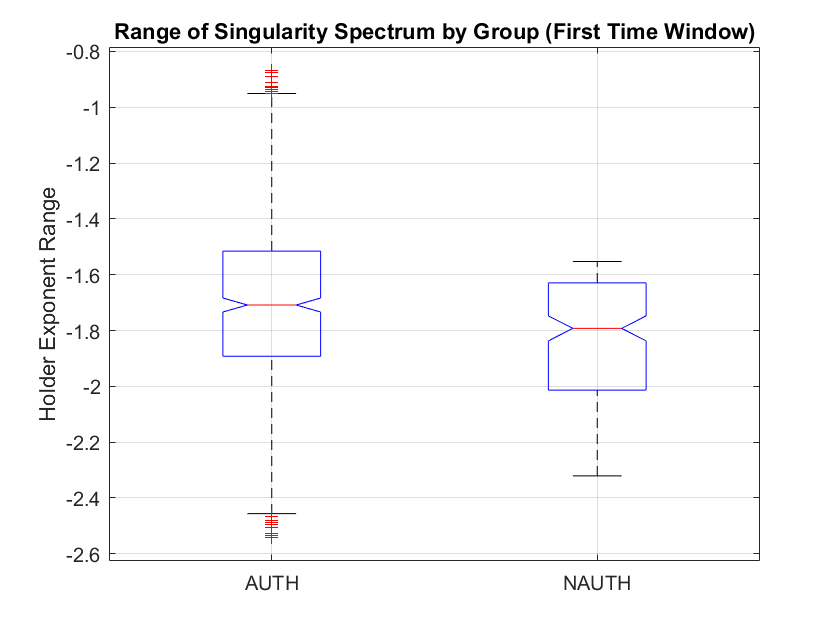

figure
boxplot(allFeatures(:,featureindices.ARfeatures(1)),allLabels,'notch','on')
ylabel('Holder Exponent Range')
title('Range of Singularity Spectrum by Group (First Time Window)')
grid on

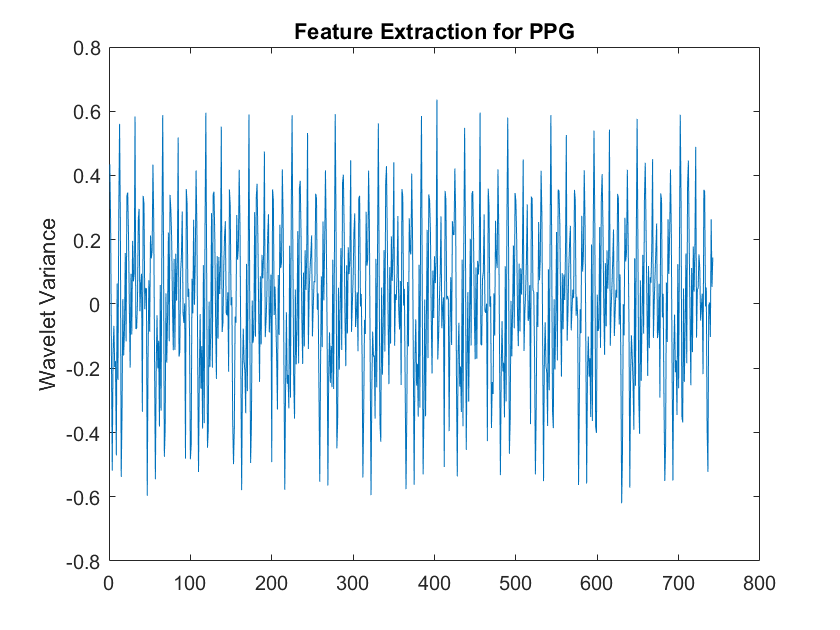


plot(allFeatures(:,featureindices.WVARfeatures(1)))
ylabel('Wavelet Variance')
title('Feature Extraction for PPG')

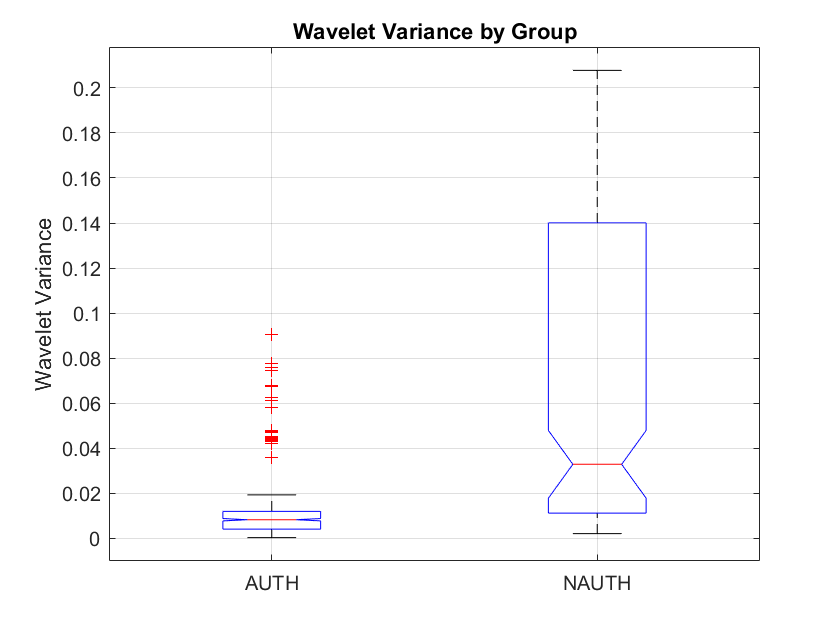

boxplot(allFeatures(:,featureindices.WVARfeatures(end)),allLabels,'notch','on')
ylabel('Wavelet Variance')
title('Wavelet Variance by Group')
grid on


%features = [trainFeatures; testFeatures];

## **Feature Selection**

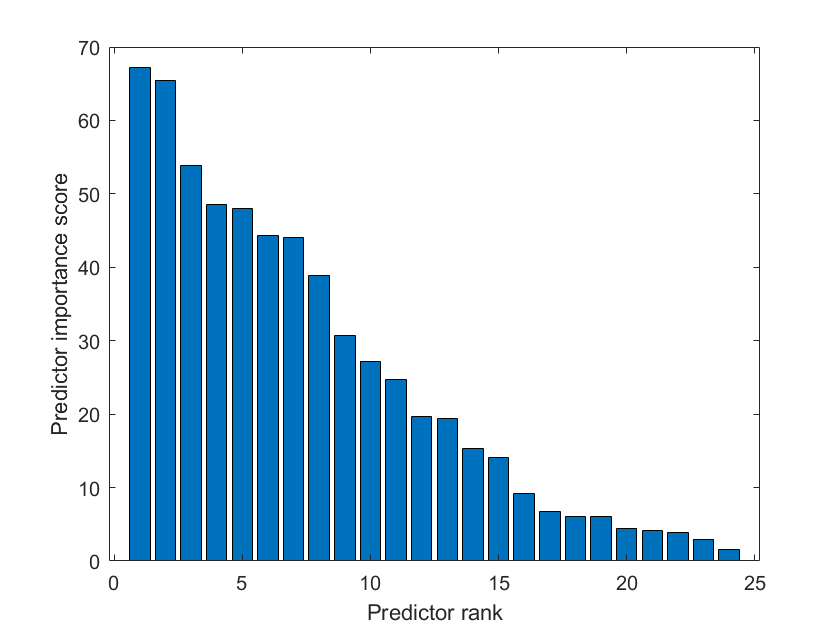

   [idx,scores] = fscchi2(trainFeatures,train_n_test_label);
   %[idx,scores] = fscmrmr(trainFeatures,train_n_test_label);
   %[idx,scores] = relieff(trainFeatures,train_n_test_label,12);
    % Select features with weight above 1
   % selected_feature_indx = find(mdl.FeatureWeights > 0.5);
    % Select 50 important features

    bar(scores(idx))
    %idx=sort(idx);
    xlabel('Predictor rank')
    ylabel('Predictor importance score')

    
    selected_feature_indx =  idx(:,1:23); 
    bar(scores(idx))
    xlabel('Predictor rank')
    ylabel('Predictor importance score')

    
    % save for future reference
    save('SelectedFeatures', 'selected_feature_indx')

## classification

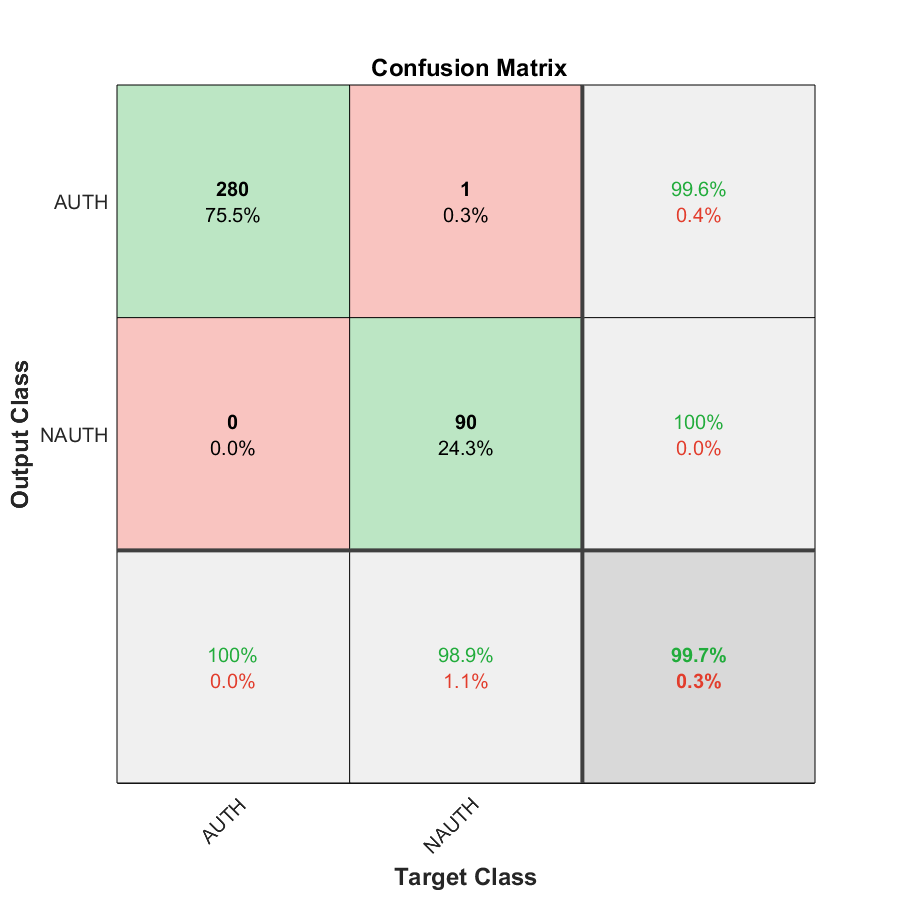

rng(1)
%{
template = templateSVM(...
    'KernelFunction','polynomial',...
   'KernelScale','auto',...
    'BoxConstraint',1,...
    'Standardize',true);
%}


%{
model = fitcecoc(...
     trainFeatures,...
     train_n_test_label,...
     'Learners',template,...
     'Coding','onevsone', ...
     'ClassNames',{'AUTH','NAUTH'});
%}

Mdl = fitcknn(trainFeatures(:,selected_feature_indx),train_n_test_label);
%Mdl = fitcensemble(trainFeatures(:,selected_feature_indx),train_n_test_label);
%Mdl = fitcgam(trainFeatures(:,selected_feature_indx),train_n_test_label);
 kfoldmodel = crossval(Mdl,'KFold',10);
classLabels = kfoldPredict(kfoldmodel);
loss = kfoldLoss(kfoldmodel);

predLabels = predict(Mdl,testFeatures(:,selected_feature_indx));

%predLabels = predict(model,testData1);

%[label,score]=predict(model,testFeatures);
%classOrder = model.ClassNames;
%correctPredictions = strcmp(predLabels,testLabel);
correctPredictions = strcmp(predLabels,train_n_test_label);
[confusionMatrix] = confusionmat(train_n_test_label,predLabels);
plotconfusion(categorical(train_n_test_label),categorical(predLabels));

%mdlSVM = fitcsvm(testFeatures,predLabels,'Standardize',true);
%mdlSVM = fitPosterior(mdlSVM);





## calculate prediction results

truePositive = confusionMatrix(1,1);
falsePositive = sum(confusionMatrix(:,1)) - confusionMatrix(1,1);
falseNegative = sum(confusionMatrix(1,:)) - confusionMatrix(1,1);
trueNegative = confusionMatrix(2,2);

precision = truePositive / (truePositive + falsePositive);
recall = truePositive / (truePositive + falseNegative);
trueNegativeRate = trueNegative / (trueNegative+falsePositive);
falseNegativeRate = falseNegative / (falseNegative+truePositive);
falsePositiveRate= 1 - trueNegativeRate;
truePositiveRate= truePositive/(truePositive + falseNegative);
f1 = 2 * precision * recall / (precision + recall);
EER=(falsePositive+falseNegative) / (truePositive+falsePositive+falsePositive+trueNegative);

## display result

%testAccuracy = sum(correctPredictions) / length(testLabel)*100
testAccuracy = sum(correctPredictions) / length(train_n_test_label)*100;

confusionMatrixTable = array2table([truePositive falsePositive;...
    falseNegative trueNegative],'VariableNames',{'Positive','Negative'},'RowNames',...
    {'Positive','Negative'});

resultTable = array2table([precision recall f1 trueNegativeRate ...
    falseNegativeRate falsePositiveRate],'VariableNames',{'Precision','Recall','F1_Score',...
    'True Negative Rate', 'False Negative Rate', 'False Positive Rate' },'RowNames',...
    {'value',});

disp(confusionMatrixTable);

                Positive    Negative
                ________    ________

    Positive      280           1   
    Negative        0          90   



disp(resultTable);

             Precision    Recall    F1_Score    True Negative Rate    False Negative Rate    False Positive Rate
             _________    ______    ________    __________________    ___________________    ___________________

    value     0.99644       1       0.99822          0.98901                   0                  0.010989      



AUC Curve


%[Xsvm,Ysvm,Tsvm,AUCsvm] = perfcurve(predLabels,score(:,1),'AUTH');
%[Xsvm1,Ysvm2,Tsvm2,AUCsvm2] = perfcurve(predLabels,score(:,2),'NAUTH');
%plot(Xsvm,Ysvm)
%xlabel('False positive rate') 
%ylabel('True positive rate')
%title('ROC for Classification')



